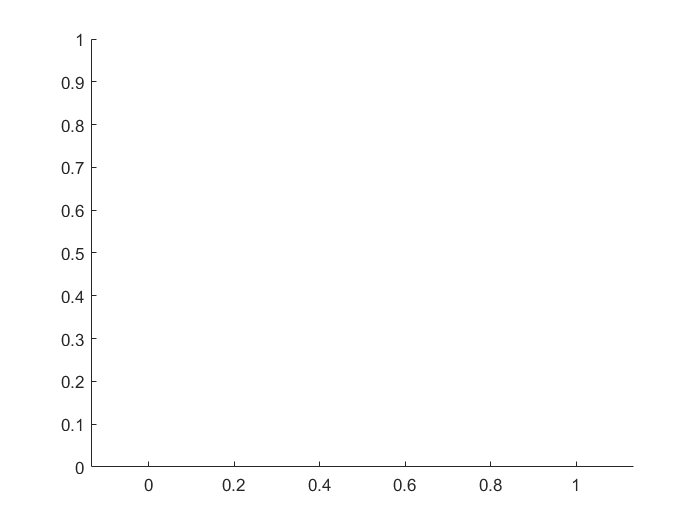

v = '11022111033304402220';
a_i = [2;1];
d = 1;
clf;
ax = axes;
hold(ax,'on');
axis(ax,'equal')

hex = d/(2*sin(pi/6))*[cos(2*pi*[1:6 1]/6);sin(2*pi*[1:6 1]/6)];
min_x = a_i(1,1);
max_x = a_i(1,1);
min_y = a_i(2,1);
max_y = a_i(2,1);
direction = 1;
dis_x = 1;
dis_y = 1;
p = a_i;
%     _ 1
% 6 /   \2
% 5 \ _ /3
%     4
current_position = a_i;
length(v)

ans = 20

for i = 1:length(v)
    [rownum,colnum]=size(p);
    if (v(i) == '1')
        current_position(1,1) = current_position(1,1)+dis_x;
        current_position(2,1) = current_position(2,1)+dis_y;
        p = [p current_position];
    elseif (v(i) == '2')
        current_position(1,1) = current_position(1,1)-dis_x;
        current_position(2,1) = current_position(2,1)-dis_y;
        p = [p current_position];
    elseif (v(i) == '3')
        direction = direction +1;
        if(direction == 7)
            direction = 1;
        end
    elseif (v(i) == '4')
        direction = direction - 1;
        if(direction == 0)
            direction = 6;
        end
    end
    if (direction == 1)
        dis_x = 1;
        dis_y = 1;
    elseif (direction == 2)
        dis_x = 1;
        dis_y = 0;
    elseif (direction == 3)
        dis_x = 0;
        dis_y = -1;
    elseif (direction == 4)
        dis_x = -1;
        dis_y = -1;
    elseif (direction == 5)
        dis_x = -1;
        dis_y = 0;
    elseif (direction == 6)
        dis_x = 0;
        dis_y = 1;
    end
end

